这是一个GITT导出数据的数据处理，land导出数据时为最后两次循环，同时找到最后一次循环的开始，保留倒数第二次循环的最后一位，将前面的删除。

# 输入

## 参数设置

%时间/s
T=1200;
%正极材料晶胞体积/A^3
V=101.542;
%电极面积/cm^2
S=1.54;
%正极材料质量/g
m=2.152*10^(-3);
%正极材料摩尔质量g/mol
M=94.34;

## 读取文件

% 读取Excel文件
filename = 'xxx.xlsx';  % 请在此处替换为您文件的实际路径
data = readtable(filename);  % 读取Excel表格

# 画time-voltage

% 取出第三列为E，第二列为I
t=data{:, 1};
E = data{:, 3};  % 第三列数据作为E向量
I = data{:, 2};  % 第二列数据作为I向量

% 新建一个与向量E同样大小的矩阵t
t = t-t(1);

% 绘制散点图
figure;
scatter(t, E,"filled");
xlabel('time/s');
ylabel('voltage/V');
hold off

# 画t^(1/2)-voltage

% 对向量I进行是否等于0的逻辑判断，结果保存为向量I1
I1 = (I == 0);

% 初始化变量
a = [];  % 存储I1从1变成0的索引
b = [];  % 存储I1从0变成1的索引
c = [];  % 存储I1从0变成1的索引
E1 = []; % 存储E1向量
E2 = []; % 存储E2向量
E0 = []; % 存储E0向量
dEt = []; % 存储dEt（E2-E1）
dEs = []; % 存储dEs（E0的差分）

% 查找I1中从1变成0的位置（a）和从0变成1的位置（b和c）
for i = 2:length(I1)
    if I1(i-1) == 1 && I1(i) == 0
        a = [a; i];  % 记录I1从1变为0的位置
        b = [b; i-1];  % 记录I1从0变为1的位置
    elseif I1(i-1) == 0 && I1(i) == 1
        c = [c; i-1];  % 记录I1从0变为1的位置
    end
end

% 取出b的位置的向量E为向量E1
E1 = E(b);

% 删除E1最后一个元素
E1 = E1(1:end-1);

% 取出c的位置的向量E为向量E2
E2 = E(c);

%画脉冲时间的Ek-tk1/2

% 取出对应的Ek和tk,取位置靠后更稳定的点
Ek = E(b(50): c(50));  % 向量Ek
tk = t(b(50): c(50));  % 向量tk

% 绘制脉冲时间图
figure;
scatter(tk.^1/2, Ek,"filled");
xlabel('tk^(1/2)');
ylabel('Ek');

# 画D-voltage

% 计算dEt = E2 - E1
dEt = E2 - E1;
% 删除dEt最后一个元素
dEt = dEt(1:end-1);

% 取出a的位置的向量E为E0
E0 = E(a);

% 计算dEs = E0下一列与上一列的差
for i = 2:length(E0)-1
    dEs(i-1) = E0(i+1) - E0(i-1);  % 计算E0的差分
end
dEs=dEs';

% %计算扩散系数
D=4/(pi*T)*(m*V/M/S)^2*(dEs ./ dEt).^2;

% 删除E2最后一个元素
E2 = E2(1:end-1);

% 找到电流开始变成负值的位置数值m
m = find(I < 0, 1);

% 对比向量b和m，找到b与m相等的针对向量b位置n
n = find(b > m, 1);  % 找到向量b比m大的第一个位置n

% 绘制散点图
figure;
scatter(E2(1:n), D(1:n),"filled");
hold on;
scatter(E2(n:end), D(n:end),"filled");
xlabel('voltage/V');
ylabel('D');
hold off

# 输出文件

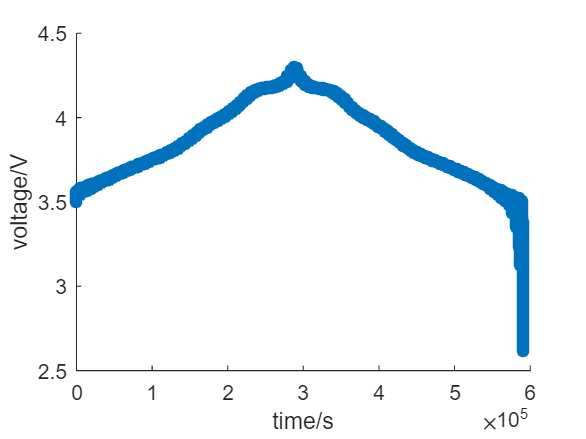

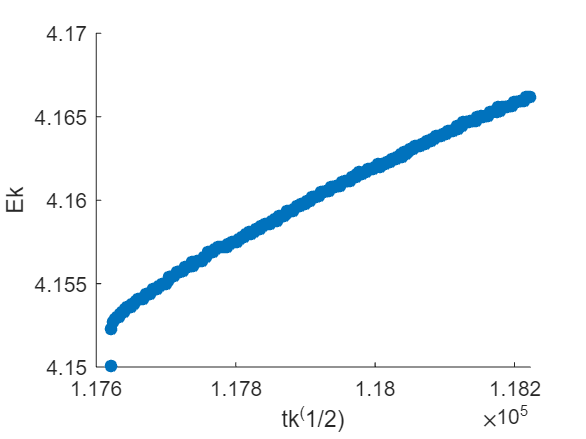

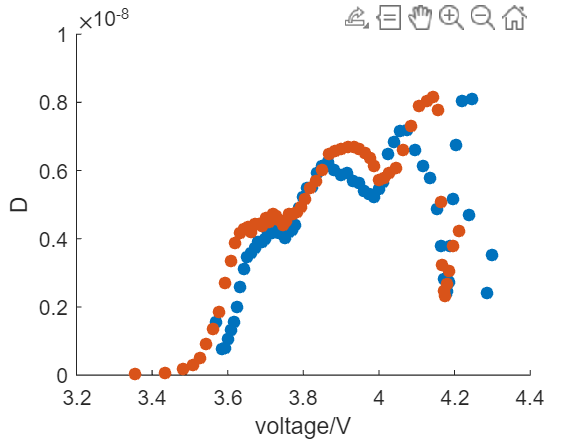

% 输出为txt文件
writematrix([t, I, E], '时间-电流-电压.txt', 'Delimiter', 'tab');  % 输出到txt文件，制表符分隔
writematrix([tk.^1/2, Ek], '时间0.5-电压.txt', 'Delimiter', 'tab');  % 输出到txt文件，制表符分隔
writematrix([E2(1:n), D(1:n)], '充电电压-扩散系数.txt', 'Delimiter', 'tab');  % 输出到txt文件，制表符分隔
writematrix([E2(n:end), D(n:end)], '放电电压-扩散系数.txt', 'Delimiter', 'tab');  % 输出到txt文件，制表符分隔